# Cleaning up ECG Data Contaminated with Sinusoidal Interference

This live script is based on the discussion in MATLAB Exercise 8.5 of 

### "Discrete-Time Signals and Systems: A MATLAB Integrated Approach"

A data file containing the output signal of an ECG sensor contaminated with 60 Hz sinusoidal interference is provided.  The goal of the exercise is to design an appropriate notch filter to reduce the effect of this sinusoidal interference, and provide a cleaner ECG signal.

clear all
load noisyECG.mat
whos

  Name         Size            Bytes  Class     Attributes

  t         3600x1             28800  double              
  x         3600x1             28800  double              



#### Graph the noisy ECG signal

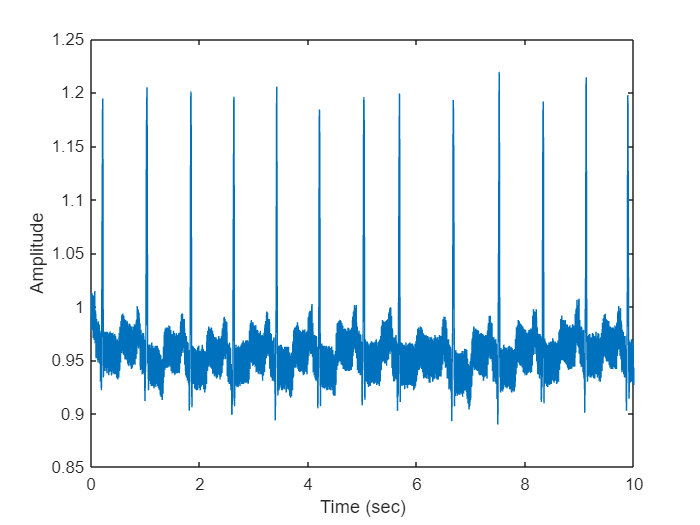

plot(t,x);
axis([0,10,0.85,1.25]);
xlabel('Time (sec)');
ylabel('Amplitude');

#### Zoom in to see the sinusoidal interference up close

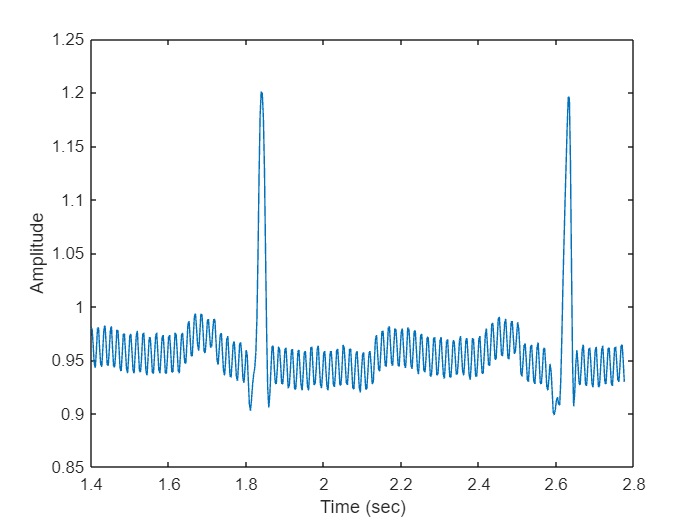

plot(t(501:1000),x(501:1000));
axis([1.4,2.8,0.85,1.25]);
xlabel('Time (sec)');
ylabel('Amplitude');

#### Compute and graph the spectrum

We will use the function fft(...) to compute the ECG spectrum. The dB magnitude will be graphed against actual frequencies in Hz.  Notice the spikes at $\pm 60$ Hz.

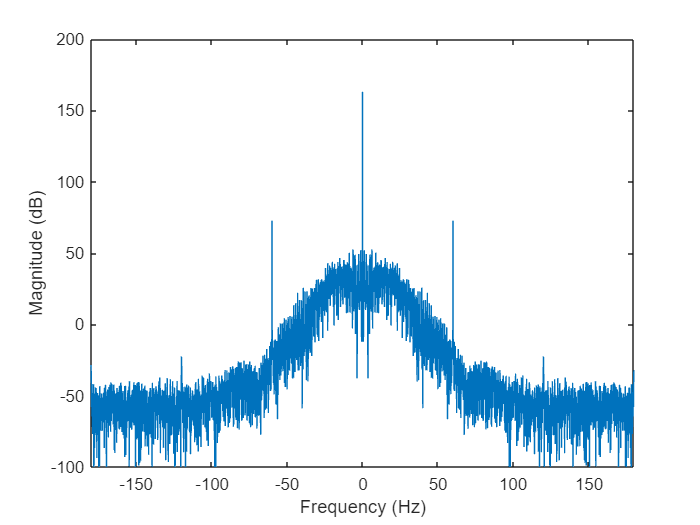

Xk = fft(x);
magdB = 20*log(abs(fftshift(Xk)));
frq = [0:3599]/3600*360-180;
plot(frq,magdB);
axis([-180,180,-100,200]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

#### Zoom in to the magnitude spectrum to see the interference up close

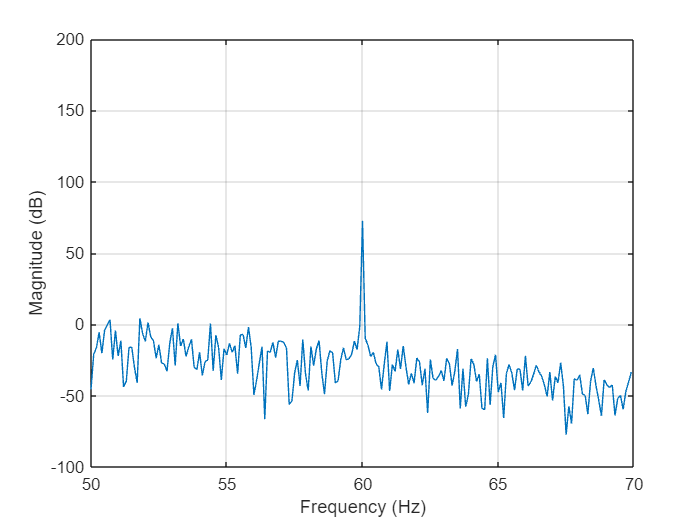

plot(frq(2300:2500),magdB(2300:2500)); grid;
axis([50,70,-100,200]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

#### Design notch filter

A notch filter with center frequency $\Omega_{0}$ and width $\Omega_{b}$ has the system function


$$H\left(z\right) = 
\frac {K\,\left(z^{2}-2\,\cos\left(\Omega_{0}\right)\,z+1\right)}  {z^{2}-2r\,\cos\left(\Omega_{0}\right)\,z+r^{2}} $$


where $r$ is the pole radius computed as $r=1-\frac{\Omega_{b}}{2}$ (see Section 8.3.2).  The function ss_notchpar(...) is used for computing the parameters of the notch filter.

fs = 360;                           % Sampling rate
f0 = 60;                            % Center frequency
fb = 6;                             % Allow 10 Hz width
Omg0 = 2*pi*f0/fs;                  % Angular center frequency
Omgb = 2*pi*fb/fs;                  % Angular bandwidth
[r,gain,zrs,pls] = ss_notchpar(Omg0,Omgb)

r = 0.9476

gain = 0.9504

zrs =    0.5000 + 0.8660i
   0.5000 - 0.8660i


pls =    0.4738 + 0.8207i
   0.4738 - 0.8207i


#### Graph the pole-zero diagram for the notch filter designed

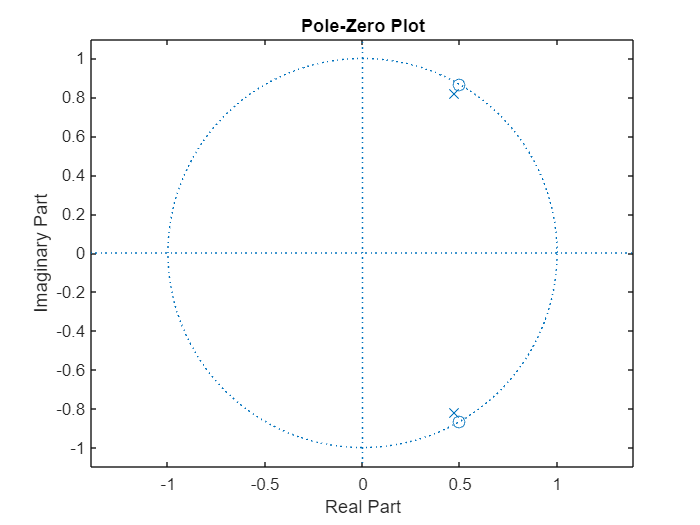

zplane(zrs,pls);  % Pole-zero diagram

#### Analyze notch filter in the frequency domain

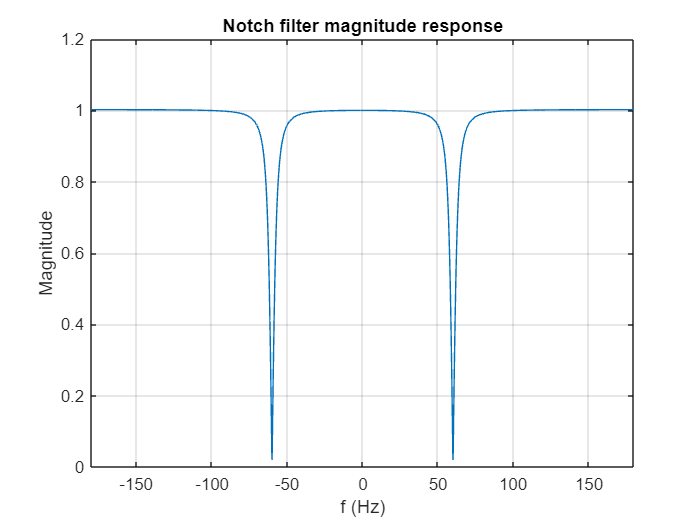

Omega = [-1:0.001:1]*pi;
mag = ss_freqz(zrs,pls,gain,Omega);
plot(Omega/(2*pi)*fs,mag); grid;
axis([-180,180,0,1.2]);
xlabel('f (Hz)');
ylabel('Magnitude');
title('Notch filter magnitude response');

#### Filter the signal and graph the result

The function ss_notchf() implements the notch filter using the block diagram in Fig. 8.12.

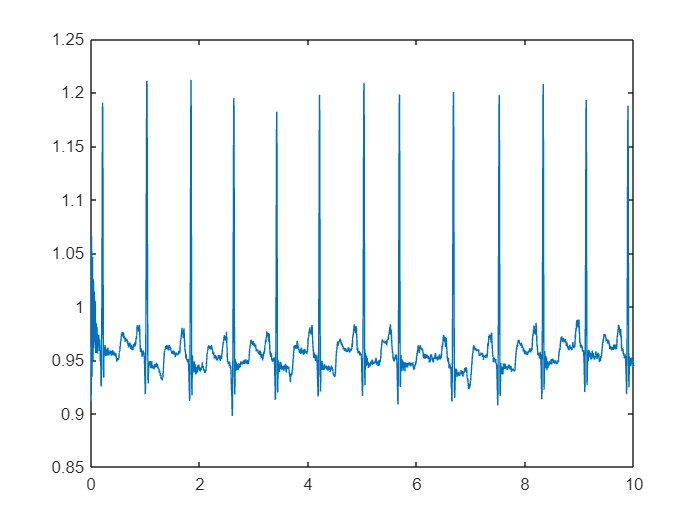

buffer=zeros(2,1);
y = ss_notchf(x,Omg0,r,gain,buffer);
plot(t,y);

#### Zoom in

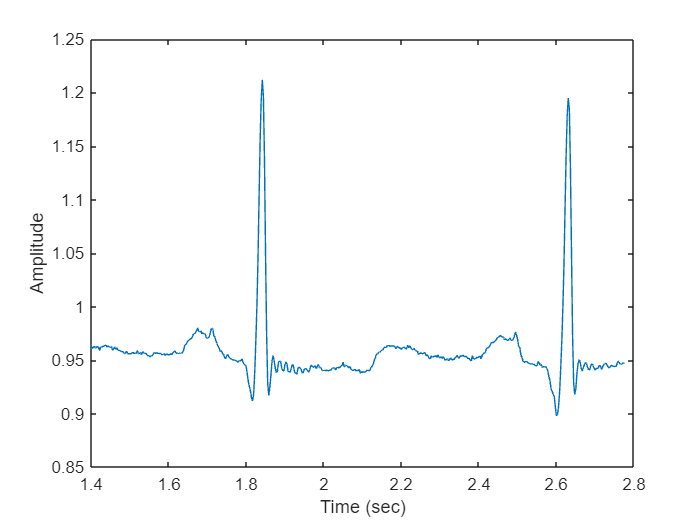

plot(t(501:1000),y(501:1000));
axis([1.4,2.8,0.85,1.25]);
xlabel('Time (sec)');
ylabel('Amplitude');

#### Compute and graph the spectrum of the clean signal

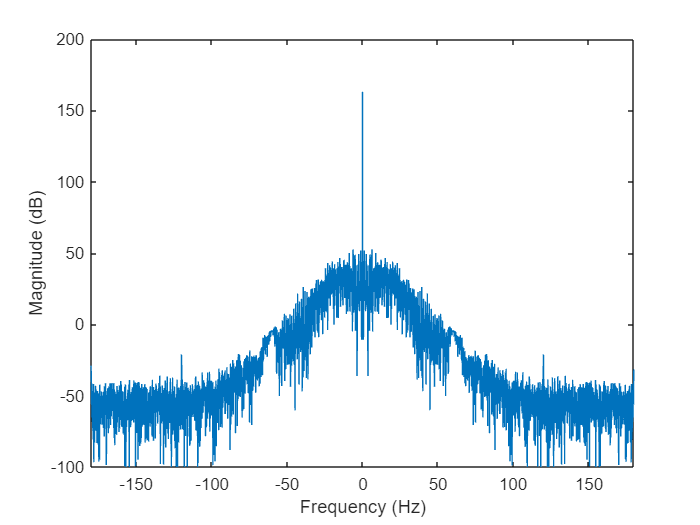

Yk = fft(y);
magdB2 = 20*log(abs(fftshift(Yk)));
plot(frq,magdB2);
axis([-180,180,-100,200]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

#### Zoom in to the magnitude spectrum

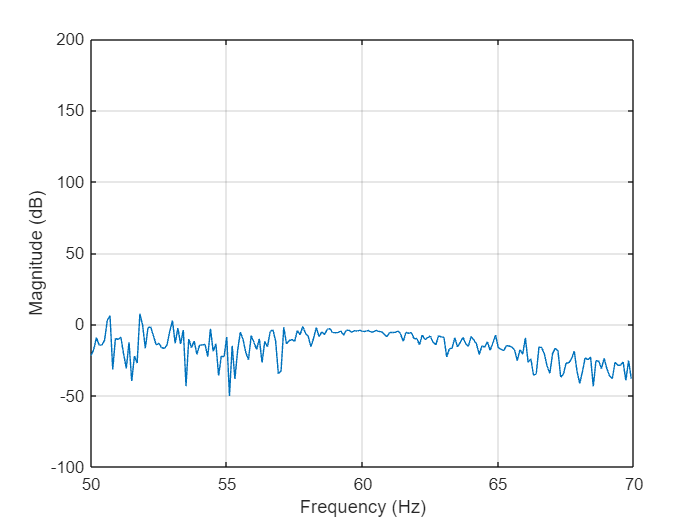

plot(frq(2300:2500),magdB2(2300:2500)); grid;
axis([50,70,-100,200]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');